# Check raw data for goodness

Sam Michalka - Neurotech 2023

Garbage in, garbage out.

We are going to check our raw data to make sure it's not garbag.

First, is it the right size?

It should have 6 columns and a sampling rate of around 1000 Hz.

if size(lsl_data,2) ~=6
    warning("Wrong number of channels")
end

Fs = 1000;
actualFsmed = 1/median(diff(lsl_data(:,1)))
actualFsmean = 1/mean(diff(lsl_data(:,1)))
if abs(actualFsmean-Fs) > 10 || abs(actualFsmed-Fs) > 10
    warning("Potential issue with sampling rate")
end


## Look at a plot of the data in the time domain

If you zoom in, it should look something like this after we filter the data (high pass).

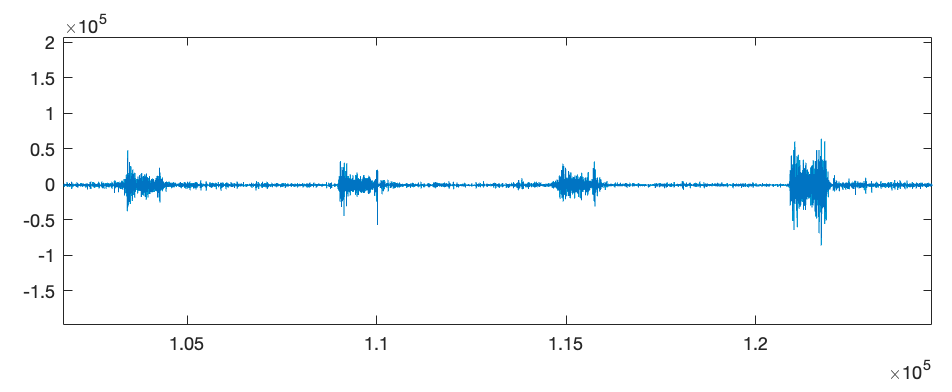

x = highpass(lsl_data(:,2),20,1000);
figure;
plot(lsl_data(:,1)-lsl_data(1,1),x); xlim([5 50]); 

## Check the frequency domain

First, we're going to look at the data in the frequency domain. 

We high pass filter the data. We should see that there is energy in the 20 to 50 Hz range. 

If you see a lot of energy (sharp peaks) in the 60, 120, and/or 180 Hz. This indicates that the recording has a lot of electrical interference. This can happen if there is poor contact with the skin or if the armband is close to a source of electrical noise.

If the plots below have high electrical noise, you may want to add in a notch filter. The notch filter removes energy from a specific frequency band. If there is high electrical noise, you'll probably want to add an additional filter to all of the channels of your data. 

y = fft(x);
n = length(x);          % number of samples
%f = (0:n-1)*(Fs/n);     % frequency range
%power = abs(y).^2/n;    % power of the DFT
% Shift the values to make fft
y0 = fftshift(y);         % shift y values
f0 = (-n/2:n/2-1)*(Fs/n); % 0-centered frequency range
power0 = abs(y0).^2/n;    % 0-centered power

figure
subplot(2,1,1);
plot(x);  %ylim(.25*[-10^6 10^6])
subplot(2,1,2)
plot(f0,power0)
xlabel('Frequency')
ylabel('Power')
xlim([30 500])


### A notch filter here to remove electrical noise

Do a notch filter and look at the data.

You'll need to run the bandstop() code for each channel as part of your preprocessing for trials.

x = bandstop(x,[58 62],Fs);
x = bandstop(x,[118 122],Fs);
x = bandstop(x,[178 182],Fs);

y = fft(x);
n = length(x);          % number of samples
%f = (0:n-1)*(Fs/n);     % frequency range
%power = abs(y).^2/n;    % power of the DFT
y0 = fftshift(y);         % shift y values
f0 = (-n/2:n/2-1)*(Fs/n); % 0-centered frequency range
power0 = abs(y0).^2/n;    % 0-centered power

figure
subplot(2,1,1);
plot(x);  ylim(.25*[-10^6 10^6])
title('with notch')
subplot(2,1,2);
plot(f0,power0)
xlabel('Frequency')
ylabel('Power')
xlim([0 500])